# State-variable linear chirp

A signal which is increasing or decreasing in frequency is called a "chirp".  a linear chirp has a constant rate of change of frequency:


$$X_a = X_m \cos \big((2\pi f_0+rt)t + \theta \big)$$


where:

    $X_m$ is the peak amplitude

    $f_0$ is the initial frequency

    $r$ is the rate of change of frequency

    $\theta$ is the initial phase

Xm = 1;
%f0 = 1/(2*pi);
f0 = 1;
r = 1;
theta = 0;

We develop a discrete (sampled) generator below.  The function [Xa] = chirp(Xm,f0,r,theta,k,T) (at the bottom) uses a sample rate Fs, sample period T and a vector of sample numbers k = 0:n to calculate samples using the cosine function.

Fs = 1024;
%duration = 1*(2*pi);
duration = 4

duration = 4

T = 1/Fs;
k = (0:T:duration)*Fs;

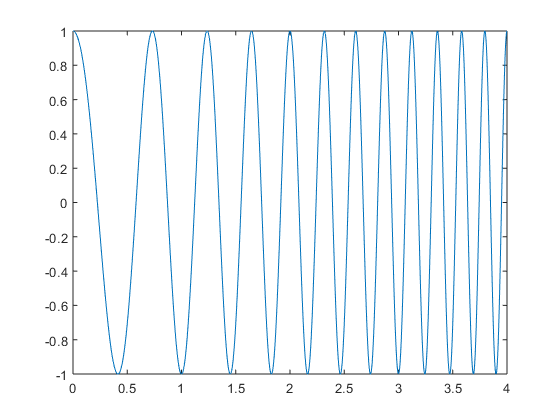

plot (k*T,chirp(Xm,f0,r,theta,k,T))

We can create a continuous sine wave using an unforced, undamped state varible system:


$$\dot X = Ax + Bu\\
Y = Cx + Du$$


where:


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
{-\omega }^2  & 0
\end{array}\right\rbrack$$



$$\begin{array}{l}
B=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack '\\
C=\left\lbrack \begin{array}{cc}
\mathrm{cos}\left(\theta \right) & -\omega \;\mathrm{sin}\;\left(\theta \right)
\end{array}\right\rbrack \\
D=0
\end{array}$$


but in the case of a linear chirp, $\omega$ is a function of time:  $\omega = 2 \pi f_0 + rt$.

Since this is a discrete system, for the state variable system:

$X_k = X_{k-1}\  e^{AT}$  (keep in mind this is a matrix exponent).

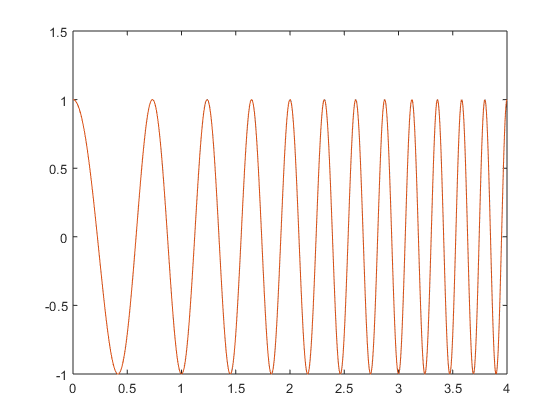

n = 2;
w = (2*pi*f0);
A = [0,1; -w^2,0]; 
B = [1,0]';
C = [cos(theta),-sin(theta)*w];
D = 0;

X = zeros(length(k),2); 
Y = zeros(length(k),1);
X(1,:) =[1,0]'; 
for n = k+2
    C = [cos(theta),-sin(theta)/w];
    Y(n-1) = C*X(n-1,:)';   
    w = 2*pi*(f0 + (r*(n-2)*T));
    A = [0,1; -w^2, -(2*pi*r)/w];     
    G = expm(-A*T);
    X(n,:) = G*X(n-1,:)';
end

y=chirp(Xm,f0,r,theta,k,T); y=y';
plot (k*T,Y)
hold on
plot (k*T,y)
hold off

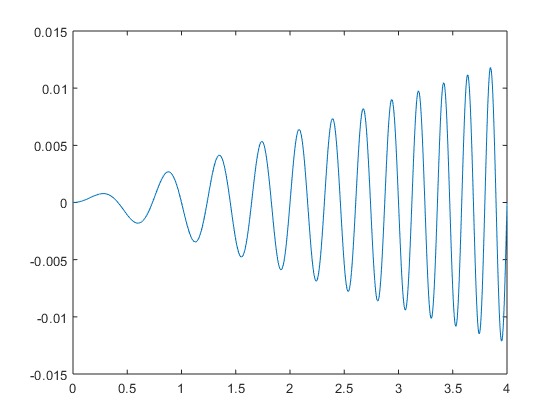

diff = Y-y;
plot (k*T,diff)

function [Xa] = chirp(Xm,f0,r,theta,k,T)
%t = k*T;
Xa = Xm* cos(((2*pi*f0*k*T) + (pi*r*(k*T).^2))+theta);
end